# Unidad 6 - TP08b

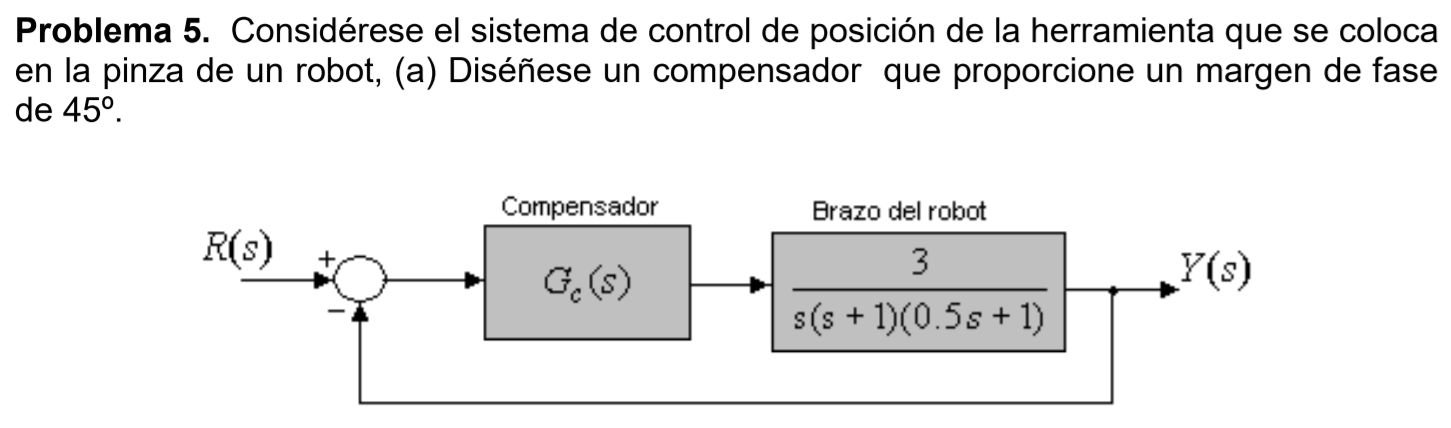

## Requisitos

- MF = 45°

## Analizamos la planta

Como no hay requerimientos de seguimiento al permanente, podríamos comenzar con diseñar una red de adelanto de fase.


$$G_C \left(s\right)=k\;\frac{\textrm{sT}+1}{\textrm{sT}\alpha +1}$$


Donde,


$$k=\;k_c \;\alpha$$



$$0<\alpha <1$$


Suponiendo $k=1$ ya que no tenemos requerimiento de error al permanente

s = tf('s');
G = 3/(s*(s+1)*(s/2+1));
H = 1;
k = 1;
margin(k*G*H);
grid on;

## Diseño

Necesitamos 45° para cumplir la condición del MF propuesta, le adicionamos entre 5° y 12° para compensar el corrimiento que sufrira por los proximos pasos de diseño.

phm = 45+10;
phm_rad = phm/180*pi;
alfa = (1-sin(phm_rad))/(1+sin(phm_rad))

Ahora obtenemos el valor de $k_c$

kc = k/alfa

Ahora buscamos la atenuación necesaria para obtener el MF calculado

Att = -20*log10(1/sqrt(alfa))

Nuevamente ingresamos con este valor de atenuación en el gráfico de bode para hallar la frecuencia a la cual se produce dicha atenuación,

bode(k*G*H);
grid on;

Observando entonces que la frecuencia $w_m =2\ldotp 37\;\frac{\textrm{rad}}{s}$. Finalmente obtenemos la ubicación del polo y cero de nuestor compensador.

wm = 2.37;
T = 1 / (sqrt(alfa)*wm)
z = wm * sqrt(alfa)
p = wm / sqrt(alfa)

Quedando finalmente nuestro compensador,


$$G_c \left(s\right)=10\;\frac{\left(s+0\ldotp 12\right)}{\left(s+1\ldotp 27\right)}$$


## Verificación

Gc = (kc*alfa) * (s*T+1)/(s*T*alfa+1);
M = feedback(G,H);
Mc = feedback(Gc*G, H)

% Bode del compensador
bode(Gc);
grid on;

% Margenes de fase y ganancia.
margin(Gc*G*H);
grid on;

% Comparativa de los bode.
bode(G*H, Gc*G*H);
grid on;
legend("Sin compensar", "Compensado");

% Respuesta al escalón
step(M, Mc);
grid on;
legend("Sin compensar", "Compensado");

% Respuesta a la rampa
[y,t]=step(M*tf(1,[1 0]), 10);
[yc,tc]=step(Mc*tf(1,[1 0]), 10);
plot(t,t,'k', t,y,'r', tc,yc,'b');
legend("Rampa unitaria", "Sin compensar", "Compensado");
grid on;

## Rediseño

Como faltó MF podríamos proponer utilizar dos compensadores  pero analicemos antes si un cambio de topología no podría funcionar.

Propongamos entonces diseñar una red de **atraso de fase.**

$G_c \left(s\right)=k\;\frac{\left(\textrm{sT}+1\right)}{\left(\textrm{sT}\beta +1\right)}$;

Donde,


$${k\;=\;k}_c \;\beta$$



$$\beta >1$$


Al igual que en el diseño anterior, al no tener requerimiento de seguimiento en régimen permanente elegimos $k=1$

Con este dato podemos entonces obtener la frecuencia a la cual nuestro sistema presenta el MF solicitado, adicionando 12° para tener un margen de diseño

bode(k*G*H);
grid on;

Quedando entonces nuestra $w_c =0\ldotp 4\;\frac{\textrm{rad}}{s}$, diseñando entonces y del mismo análisis extraemos del gráfico de magnitud que $\left|G\left(w_c \right)\right|=16\ldotp 6\;\textrm{dB}$. Esta será la atenuación que debe agregar nuestra red para que se cumpla la condición del MF. Por lo tanto,


$$\textrm{Att}=-20\;\log_{10} \left(\frac{1}{\beta }\right)$$



$$\beta ={10}^{\frac{\textrm{Att}}{20}}$$



$$k_c =\frac{k}{\beta }$$



$$\left|z\right|\le \frac{w_c }{10}$$



$$T=\frac{1}{\left|z\right|}$$



$$\left|p\right|=\frac{1}{T\beta }$$


wc = 0.4;
beta = 10^(16.6/20);
kc_r = k/beta;
z_r = wc/10
T_r = 1/z_r
p_r = 1/(T_r*beta)

## Verificación red de retraso

Gc_r = (kc_r*beta) * (s*T_r+1)/(s*T_r*beta+1);
Mc_r = feedback(Gc_r*G, H)

% Bode del compensador
bode(Gc_r);
grid on;

% Margenes de fase y ganancia.
margin(Gc_r*G*H);
grid on;

% Comparativa de los bode.
bode(G*H, Gc_r*G*H);
grid on;
legend("Sin compensar", "Compensado");

% Respuesta al escalón
step(M, Mc_r);
grid on;
legend("Sin compensar", "Compensado");

% Respuesta a la rampa
[y,t]=step(M*tf(1,[1 0]), 10);
[yc_r,tc_r]=step(Mc_r*tf(1,[1 0]), 10);
plot(t,t,'k', t,y,'r', tc_r,yc_r,'b');
legend("Rampa unitaria", "Sin compensar", "Compensado");
grid on;